**Reading the Dataset**

% Load the data from the CSV file using readmatrix (requires MATLAB R2020b or later)
data = readmatrix('../credit-card-dataset/creditcard.csv');


**Data Preprocessing**

% Display the first few rows of the data
disp(data(1:5, :));

         0   -1.3598   -0.0728    2.5363    1.3782   -0.3383    0.4624    0.2396    0.0987    0.3638    0.0908   -0.5516   -0.6178   -0.9914   -0.3112    1.4682   -0.4704    0.2080    0.0258    0.4040    0.2514   -0.0183    0.2778   -0.1105    0.0669    0.1285   -0.1891    0.1336   -0.0211  149.6200         0
         0    1.1919    0.2662    0.1665    0.4482    0.0600   -0.0824   -0.0788    0.0851   -0.2554   -0.1670    1.6127    1.0652    0.4891   -0.1438    0.6356    0.4639   -0.1148   -0.1834   -0.1458   -0.0691   -0.2258   -0.6387    0.1013   -0.3398    0.1672    0.1259   -0.0090    0.0147    2.6900         0
    1.0000   -1.3584   -1.3402    1.7732    0.3798   -0.5032    1.8005    0.7915    0.2477   -1.5147    0.2076    0.6245    0.0661    0.7173   -0.1659    2.3459   -2.8901    1.1100   -0.1214   -2.2619    0.5250    0.2480    0.7717    0.9094   -0.6893   -0.3276   -0.1391   -0.0554   -0.0598  378.6600         0
    1.0000   -0.9663   -0.1852    1.7930   -0.8633   -0.0103    1.2


% Get the number of rows and columns in the data
[num_rows, num_cols] = size(data);
fprintf('Total rows and columns: %d rows and %d columns\n', num_rows, num_cols);

Total rows and columns: 284807 rows and 31 columns



% Check for missing values by summing NaN values for each column
missing_sum = sum(isnan(data));
disp(missing_sum);

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0




% Separate fraud and non-fraud transactions
fraud = data(data(:, end) == 1, :);
non_fraud = data(data(:, end) == 0, :);

% Calculate the percentage of fraud and non-fraud transactions
fraud_percentage = 100 * size(fraud, 1) / num_rows;
non_fraud_percentage = 100 * size(non_fraud, 1) / num_rows;

fprintf('Frauds: %.2f%%\n', fraud_percentage);

Frauds: 0.17%


fprintf('Non-frauds: %.2f%%\n', non_fraud_percentage);

Non-frauds: 99.83%



% Plot the Transaction class distribution
figure;
class_counts = histcounts(data(:, end), 2);
bar([0, 1], class_counts);

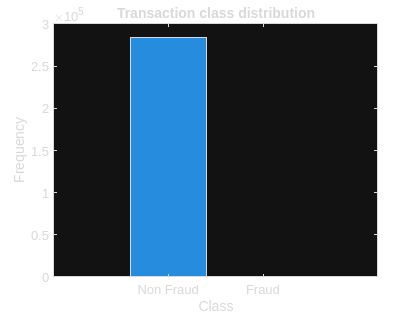

title('Transaction class distribution');
xlabel('Class');
ylabel('Frequency');
xticks([0, 1]);
xticklabels({'Non Fraud', 'Fraud'});

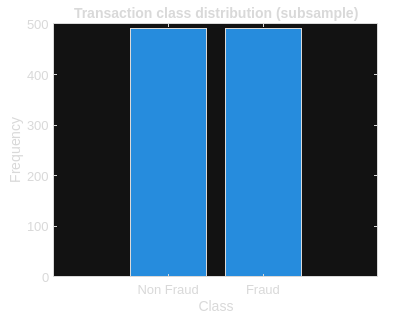


% Shuffle the data before creating the subsamples
data = data(randperm(num_rows), :);

% Extract fraud and non-fraud samples, keeping the same number of each
num_frauds = sum(data(:, end) == 1);
num_non_frauds = sum(data(:, end) == 0);
non_frauds_subsample = data(data(:, end) == 0, :);
non_frauds_subsample = non_frauds_subsample(1:num_frauds, :);

new_data = [non_frauds_subsample; fraud];
new_data = new_data(randperm(size(new_data, 1)), :);

% Plot the Transaction class distribution for the subsample
figure;
class_counts_subsample = histcounts(new_data(:, end), 2);
bar([0, 1], class_counts_subsample);
title('Transaction class distribution (subsample)');
xlabel('Class');
ylabel('Frequency');
xticks([0, 1]);
xticklabels({'Non Fraud', 'Fraud'});

**Separating the data into training and testing sets**

% Prepare the data
features = new_data(:, 1:end-1);
labels = new_data(:, end);

% Split the data into training and testing sets (70% for training)
[train_indices, test_indices] = crossvalind('HoldOut', size(new_data, 1), 0.3);
X_train = features(train_indices, :);
X_test = features(test_indices, :);
y_train = labels(train_indices, :);
y_test = labels(test_indices, :);

% Normalize the data using z-score normalization from Statistics and Machine Learning Toolbox
X_train = normalize(X_train, 'zscore');
X_test = normalize(X_test, 'zscore');

**Find the optimal K using k-fold cross-validation**

% Find the optimal K using k-fold cross-validation
k_range = 1:25;
knn_accuracy_train = zeros(length(k_range), 1);
knn_accuracy_test = zeros(length(k_range), 1);

for k_idx = 1:length(k_range)
    knn_model = customKNN(X_train, y_train, k_range(k_idx));
    y_pred_train = predict(knn_model, X_train);
    knn_accuracy_train(k_idx) = sum(y_train == y_pred_train) / numel(y_train);
    
    y_pred_test = predict(knn_model, X_test);
    knn_accuracy_test(k_idx) = sum(y_test == y_pred_test) / numel(y_test);
end

% Find the optimal K based on test accuracy
[~, optimal_k_idx] = max(knn_accuracy_test);
optimal_k = k_range(optimal_k_idx);


**Plot the k-NN accuracy versus K (training and test accuracy)**

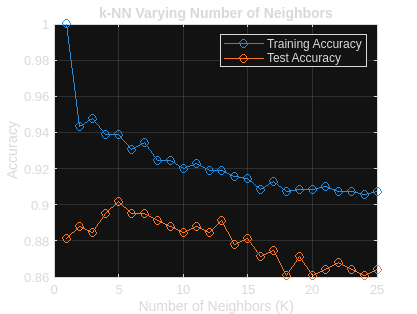

% Plot the k-NN accuracy versus K (training and test accuracy)
figure;
plot(k_range, knn_accuracy_train, 'o-', 'DisplayName', 'Training Accuracy');
hold on;
plot(k_range, knn_accuracy_test, 'o-', 'DisplayName', 'Test Accuracy');
xlabel('Number of Neighbors (K)');
ylabel('Accuracy');
title('k-NN Varying Number of Neighbors');
grid on;
legend;
hold off;

**Training the Model**

% Train the k-NN model with the optimal K using customKNN
knn_model = customKNN(X_train, y_train, optimal_k);

% Predict labels for the testing set using customKNN
knn_predicted_test_labels = predict(knn_model, X_test);

% Scoring k-NN
knn_accuracy_score = sum(y_test == knn_predicted_test_labels) / numel(y_test);
knn_precision_score = sum(y_test & knn_predicted_test_labels) / sum(knn_predicted_test_labels);
knn_recall_score = sum(y_test & knn_predicted_test_labels) / sum(y_test);
knn_f1_score = 2 * knn_precision_score * knn_recall_score / (knn_precision_score + knn_recall_score);
knn_MCC = corrcoef(y_test, knn_predicted_test_labels);

% Printing scores
fprintf('KNN Model Performance:\n');

KNN Model Performance:


%fprintf('MCC --> %.2f\n', knn_MCC);
fprintf('Accuracy:  %.2f\n', knn_accuracy_score);

Accuracy:  0.90


fprintf('Precision: %.2f\n', knn_precision_score);

Precision: 0.98


fprintf('Recall:    %.2f\n', knn_recall_score);

Recall:    0.83


fprintf('F1:        %.2f\n', knn_f1_score);

F1:        0.90


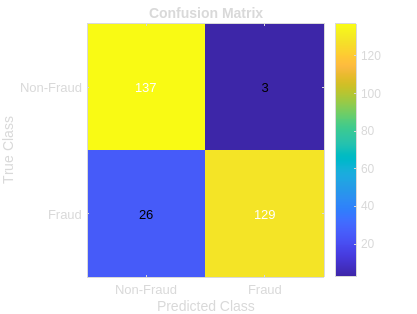


% Display the confusion matrix
conf_matrix = confusionmat(y_test, knn_predicted_test_labels);
LABELS = {'Non-Fraud', 'Fraud'};
plotConfusionMatrix(conf_matrix, LABELS);

**Function Definitions**

function plotConfusionMatrix(confMatrix, classes)
    numClasses = size(confMatrix, 1);
    figure;
    imagesc(confMatrix);
    title('Confusion Matrix');
    colorbar;
    
    textStrings = num2str(confMatrix(:), '%.0f');
    textStrings = strtrim(cellstr(textStrings));
    [x, y] = meshgrid(1:numClasses);
    hStrings = text(x(:), y(:), textStrings(:), 'HorizontalAlignment', 'center');
    midValue = mean(get(gca, 'CLim'));
    textColors = repmat(confMatrix(:) > midValue, 1, 3);
    set(hStrings, {'Color'}, num2cell(textColors, 2));
    
    xticks(1:numClasses);
    yticks(1:numClasses);
    xticklabels(classes);
    yticklabels(classes);
    xlabel('Predicted Class');
    ylabel('True Class');
end

% Define the custom KNN function
function knn_model = customKNN(X_train, y_train, k)
    knn_model = struct();
    knn_model.X_train = X_train;
    knn_model.y_train = y_train;
    knn_model.k = k;
    % No training is needed for KNN as it's a lazy learning algorithm
end

% Define the predict function for custom KNN
function y_pred = predict(knn_model, X_test)
    X_train = knn_model.X_train;
    y_train = knn_model.y_train;
    k = knn_model.k;

    num_test = size(X_test, 1);
    y_pred = zeros(num_test, 1);

    for i = 1:num_test
        % Calculate distances between the test data point and all training data points
        distances = sqrt(sum((X_train - X_test(i, :)).^2, 2));

        % Get the indices of the k-nearest neighbors
        [~, indices] = mink(distances, k);

        % Get the classes of the k-nearest neighbors
        k_nearest_classes = y_train(indices);

        % Predict the majority class among the k-nearest neighbors
        y_pred(i) = mode(k_nearest_classes);
    end
end